# Estimate of growth rate of E. coli

In this tutorial, we will use a time lapse movie of a growing *E. coli* colony to estimate the growth rate of the dividing cells.  Along the way, we will learn some image processing and regression techniques.

The data set comes from Muir Morrison at Caltech, using the same bacteria you are using. The images were taken every six minutes.

## Model for *E. coli* growth

Since our goal is to perform a regression to estimate a parameter, we of course need a model to define what the parameters are.  To develop this model, we will assume that each bacterium growth at a constant rate.  Then the total mass, $m$ of bacteria, will grow more rapidly as we get more bacteria, since *each* bactrium is growing.  We can write this as a differential equation.


$$\dot{m} = km,$$


where the dot indicates time differentiation.  The idea here is that the rate of increase of mass is proportional to the mass itself.  The growth rate, $k$, is the constant of proportionality.  We can solve this differential equation as


$$m(t) = m_0 \mathrm{e}^{kt},$$


where $m_0$ is the mass of bacteria at time zero.  You can verify that this is indeed the solution to the differential equation by differentiating the expression.

So, our goal is to estimate $k$, which has dimension of inverse time, to determine the growth rate.  The doubling time is the time it takes to double the mass, i.e., the time $t_d$ that solves


$$m = m_0\mathrm{e}^{kt_d} = 2m_0,$$


or


$$t_d = \ln 2 / k.$$


## Exploring the image stack

It's always a good idea to take a look at your data before analyzing to make sure everything is as you expect.  First, we'll load an image and look at it.

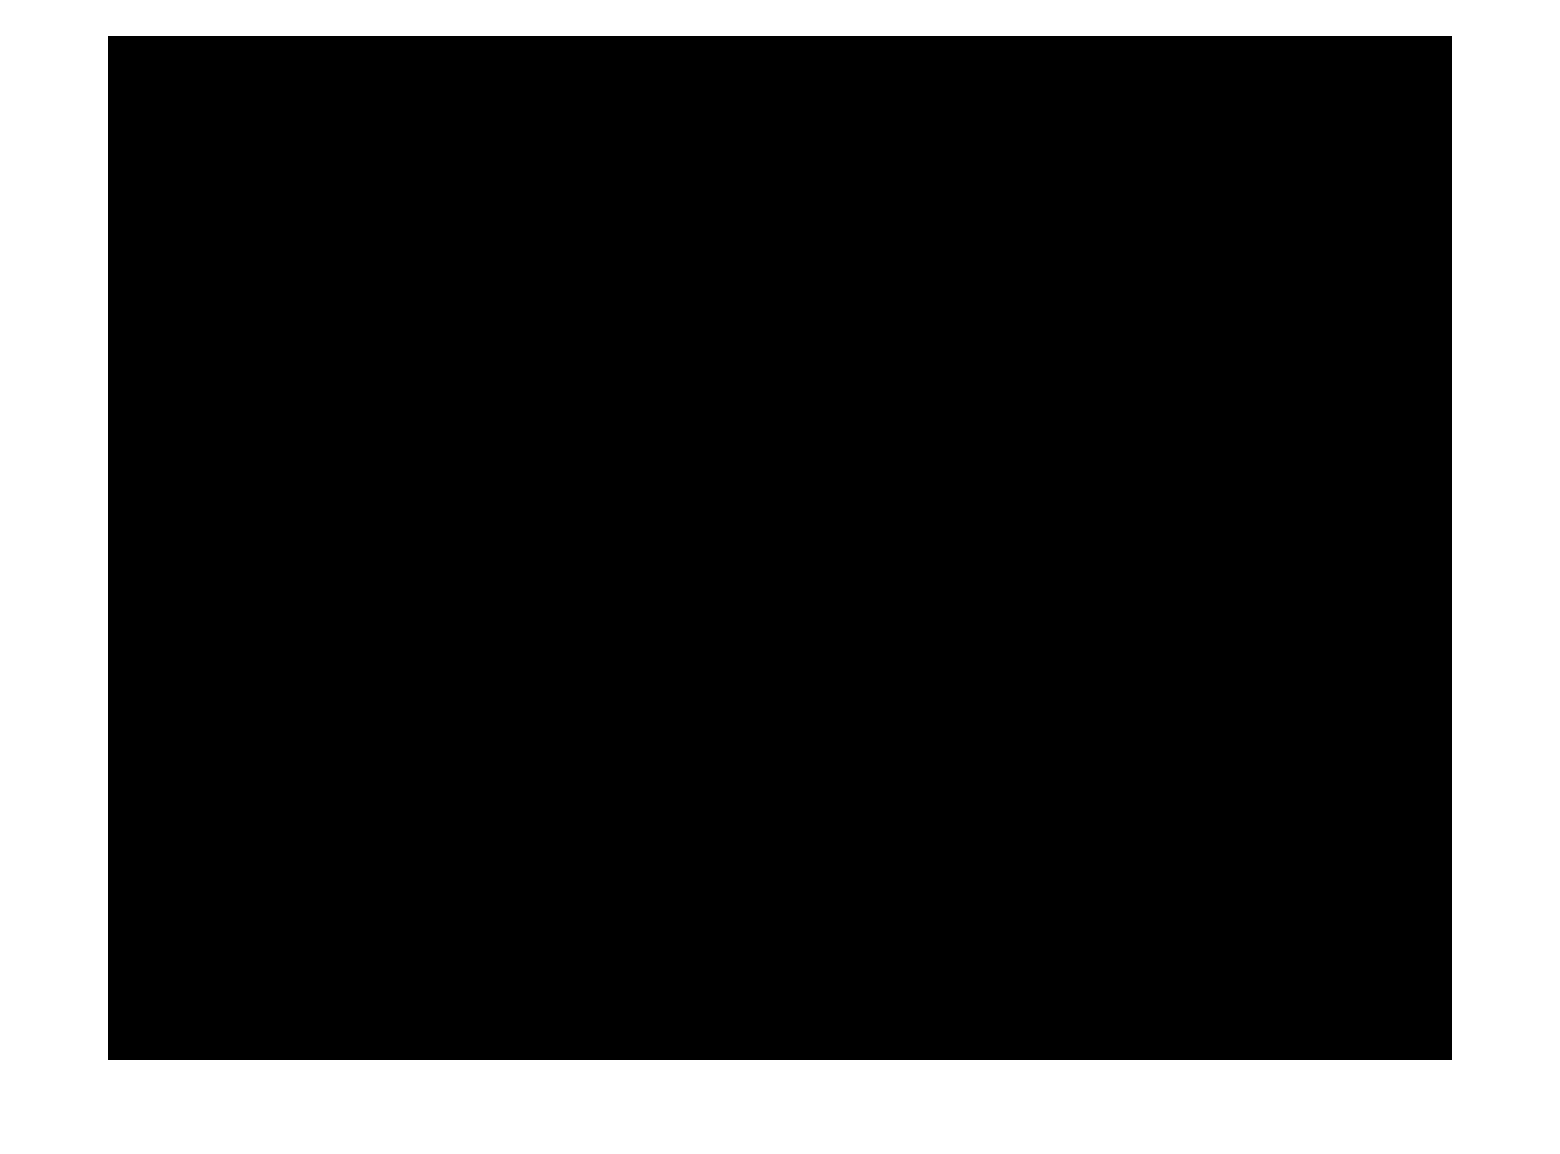

% Get a list of the image file names
cd ~/git/mbl_physiology_matlab/ecoli_growth;
dataDir = '2016-04-03-muir_dryrun';
fNames = dir(fullfile(dataDir, '*TRITC*.tif'));
fNames = {fNames.name};

% Keep the full path of file names
for i = 1:length(fNames)
    fNames{i} = fullfile(dataDir, fNames{i});
end %for

% Load the first image
im = imread(fNames{1});

% Display it
imshow(im, []);

Whoa!  It's black.  Let's look at the second image.

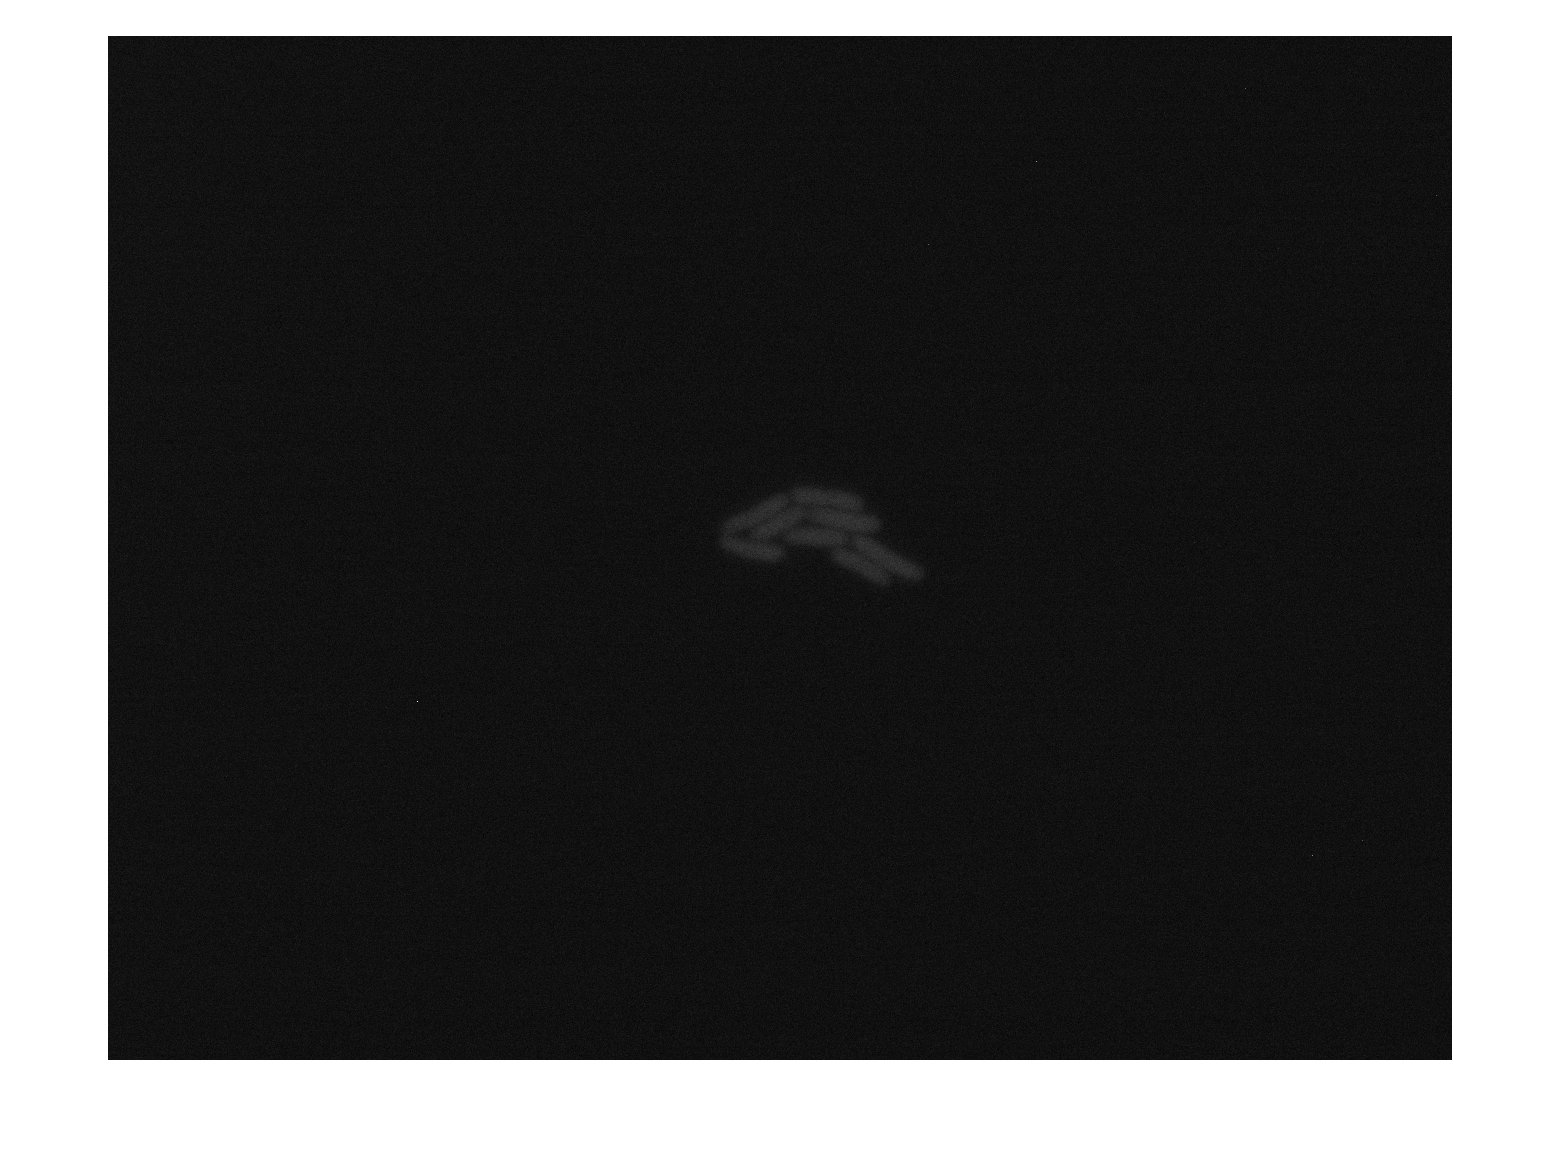

im = imread(fNames{2});
imshow(im, []);

That's better!  These images are a bit hard to see because the particular camera with which they were taken has a few hot pixels.  We can filter those out using a **median filter**, which replaces each pixel value the the median value of the pixel values around it.  So, let's look at the filtered image.  While we are at it, we will convert the image to a floating point array, and rescale it to go from zero to 1 (we'll need to do this anyway later for thresholding.  Because of Matlab's aggravating function syntax (one function, one file), we will write an anonymous function here.

imrescale = @(im) (im - min(min(im))) / (max(max(im)) - min(min(im)));

Note that this function expects the image as a double.  So, let's convert to double, rescale,  median filter, and look at our image.

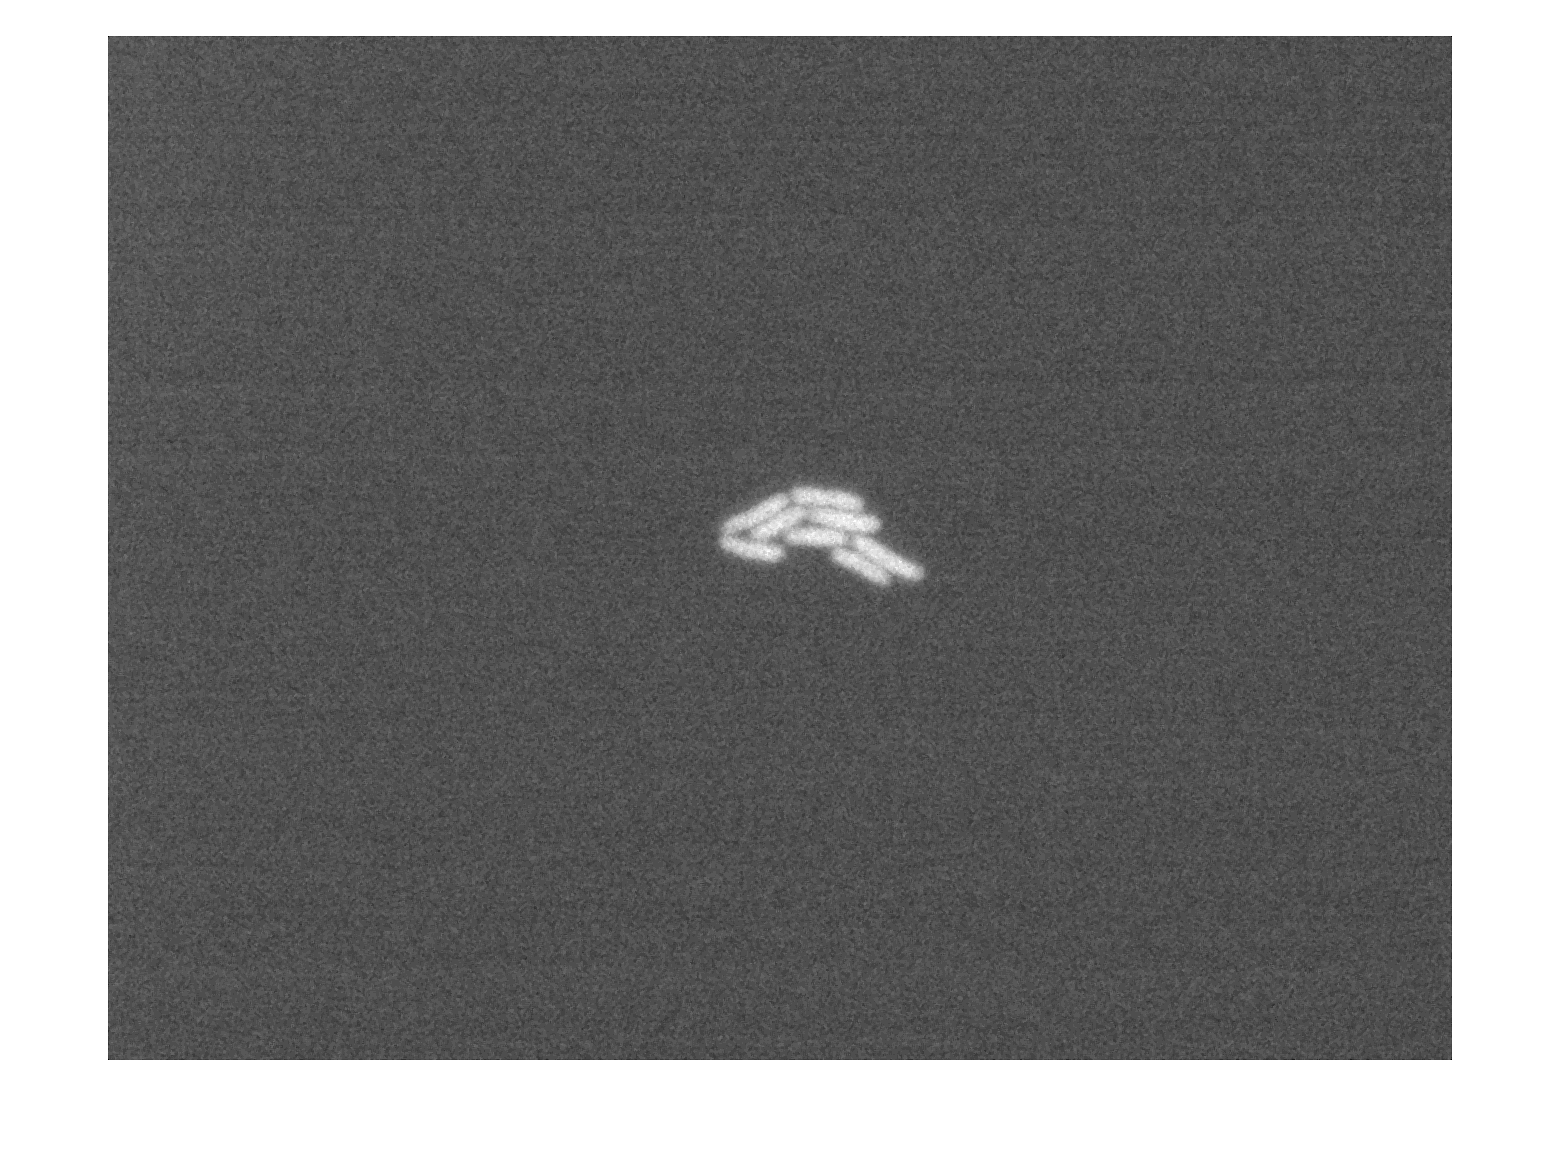

im = im2double(imread(fNames{2}));
im = imrescale(im);
im = medfilt2(im);
imshow(im, []);

This is much better.  We see the whole dynamic range and can pick out the bacteria clearly.  Since we will do this over and over, let's write a function to do so. 

impreproc = @(fName) medfilt2(imrescale(im2double(imread(fName))));

Now, let's check the last frame to see how that looks.

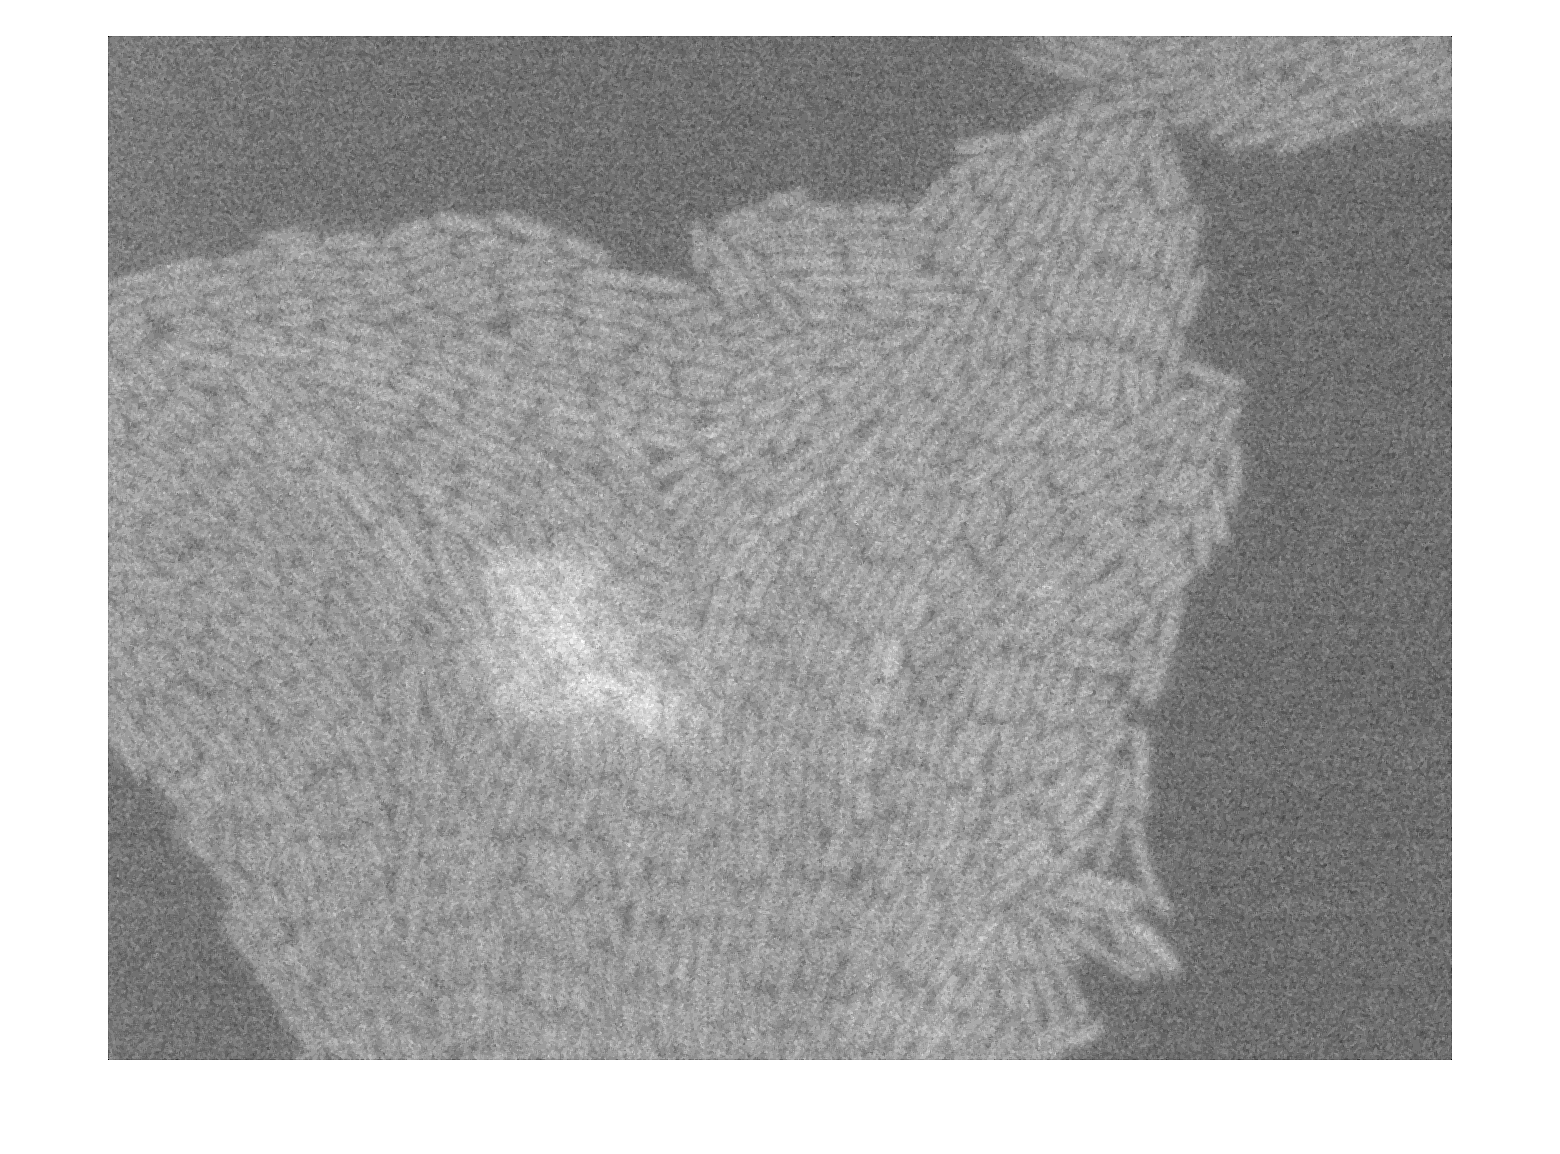

imshow(impreproc(fNames{end}), []);

Yikess!  The colony has grown out of the field of view and has become two layers think at one point.  This will mess up our growth measurement; we want a single, uncropped colony.  We can find the last frame where we have that by looking at our images.  It happens to be frame 24.

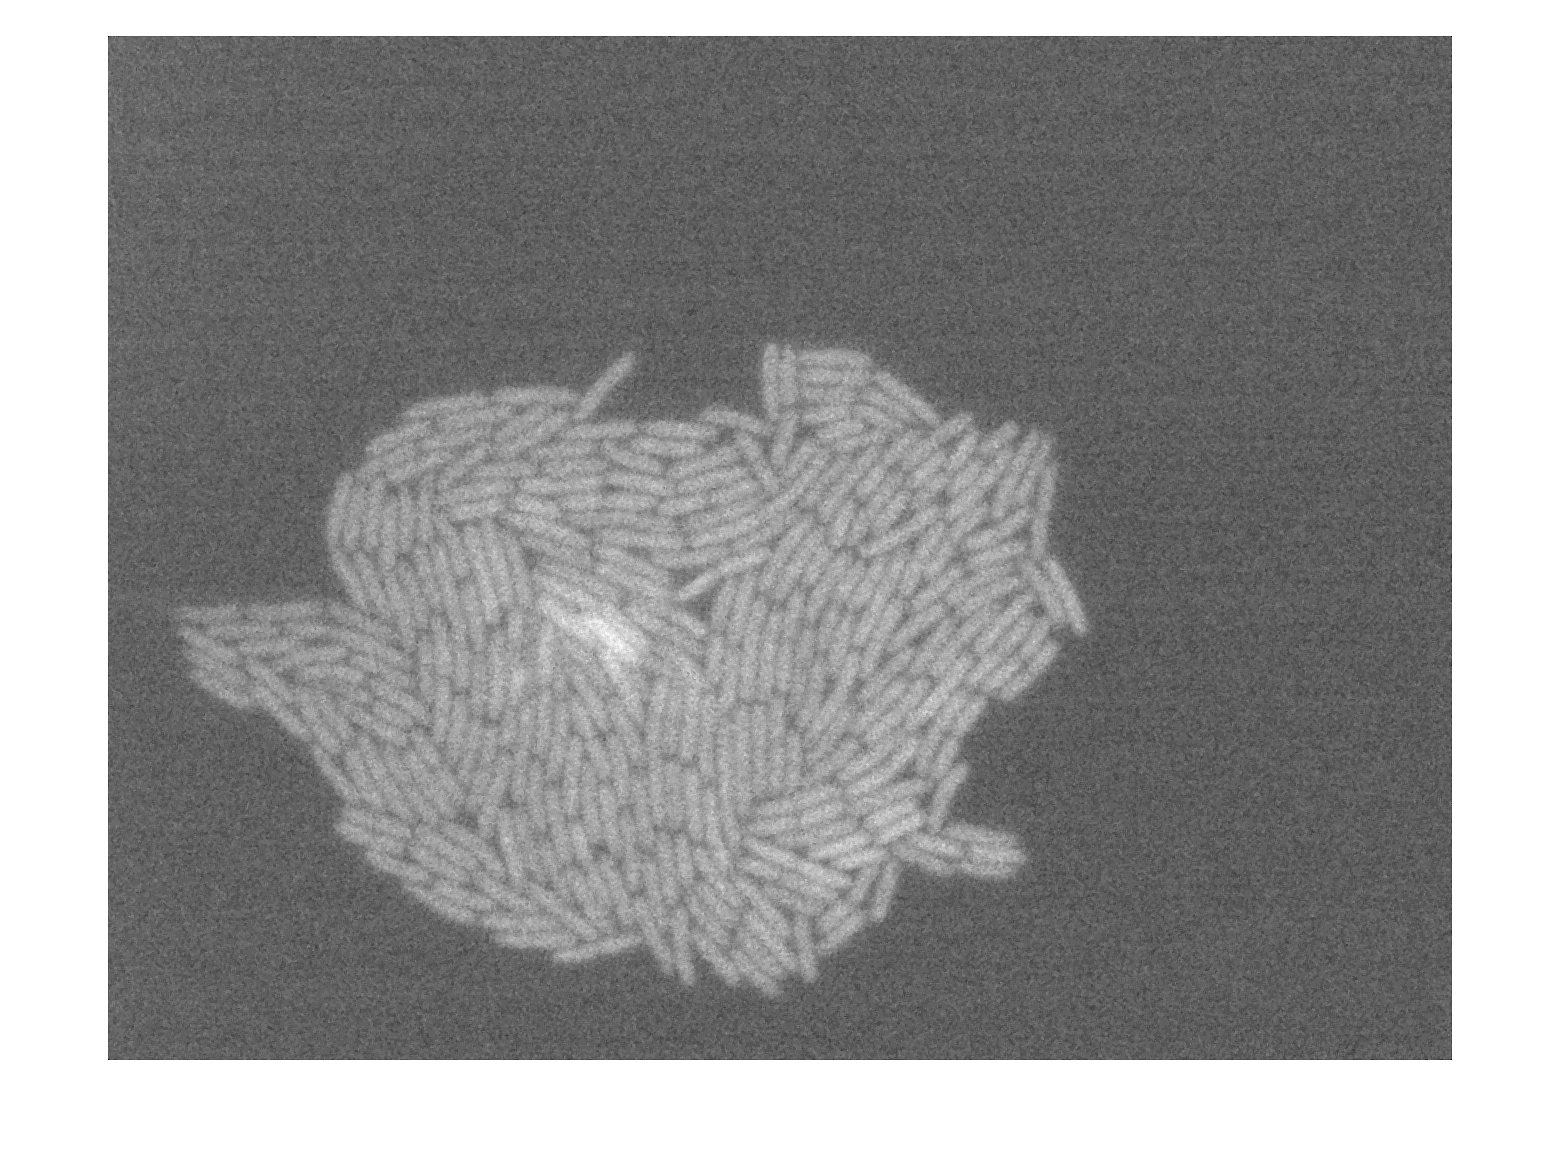

imshow(impreproc(fNames{24}), []);

So, we know frame 1 is bogus, as are frames 26 through the end.  So, we define our good frames.

goodFrames = 2:24;

Now we are ready to compute the bacterial mass from our images.

## Computing bacterial mass

The bacterial mass is proportional to the total area of the bacteria in the images.  So, $m=\alpha A,$ where $\alpha$ is the constant of proportionality.  Thus, we have


$$m(t) = \alpha A(t) = m_0 \mathrm{e}^{kt} = \alpha A_0 \mathrm{e}^{-kt}.$$


Thus,


$$A(t) = A_0 \mathrm{e}^{kt},$$


so we do not need to compute the mass to determine the growth rate $k$.  So, we just need to find the area of the bacteria in the images.

To do this, we will use a technique called **thresholding**.  The idea is that because the bacteria are expressing fluorescent protein, they are brighter than the background.  So, we assign all pixels that are bright to bacteria and those that are dark to background.  The number of bright pixels gives the bacterial area (in units of interpixel spacing squared).  So, we set a threshold pixel value, above which a pixel is decreed to be part of a bacterium.

There are several methods to automatically compute thresholds.  Otsu's method is one of the most commonly used ones.  This is implemented in Matlab with the `graythresh` function.

thresh = graythresh(im)

thresh = 0.1157

So, pixels above intensity 0.12 are considered bacterial in this image.  We can then generate a **binary image** that is white where there are bacteria (pixels above threshold) and black elsewhere.  We can generate this image using the `imbinarize` function.

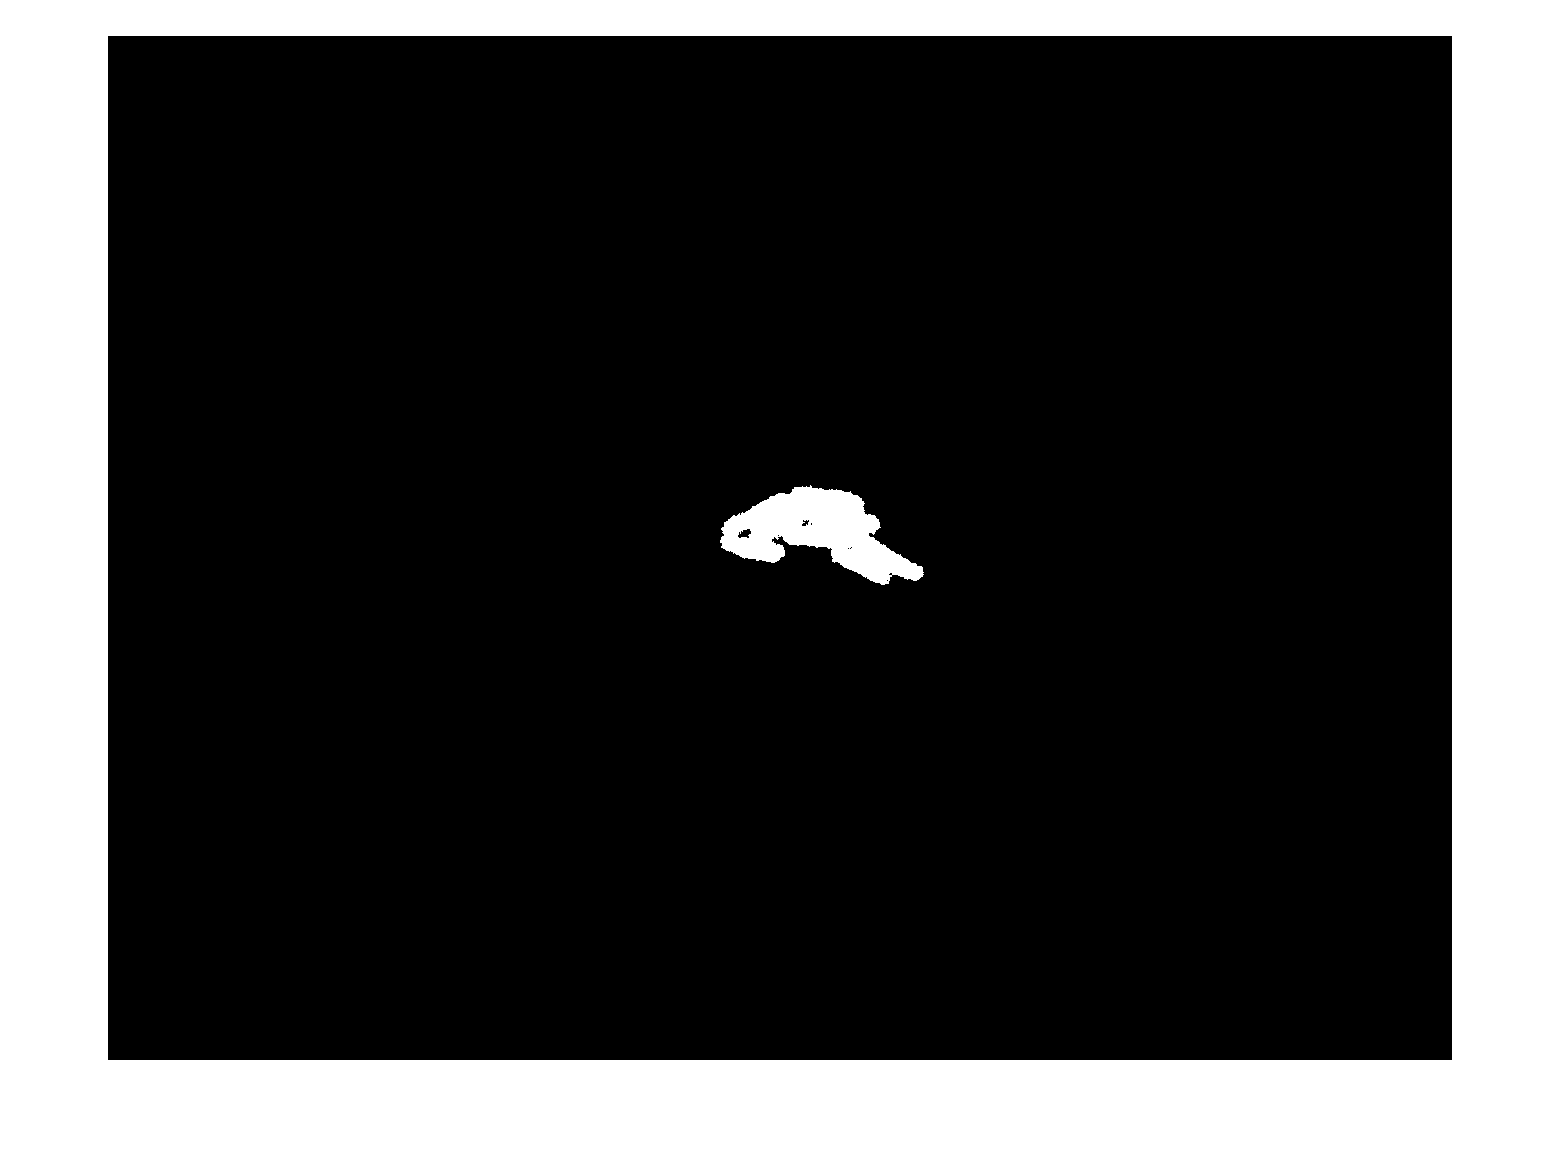

imBW = imbinarize(im, thresh);
imshow(imBW);

We did a pretty good job identifying bacteria.  To get the area, in square interpixel distance, we just sum the binary image!

area = sum(sum(imBW))

area = 10117

## Computing the area for all frames

To get the areas for each frame, we simple loop over each frame and compute the areas as we have done for frame 2.

% Initialize area array and time points with 6 minutes between frames
areas = zeros(1, length(goodFrames));
t = (goodFrames - goodFrames(1)) * 6;

% Compute areas
j = 1;
for i = goodFrames
    im = impreproc(fNames{i});
    imBW = imbinarize(im, graythresh(im));
    areas(j) = sum(sum(imBW));
    j = j + 1;
end %for

Now we can generate a plot of the bacterial area versus time.

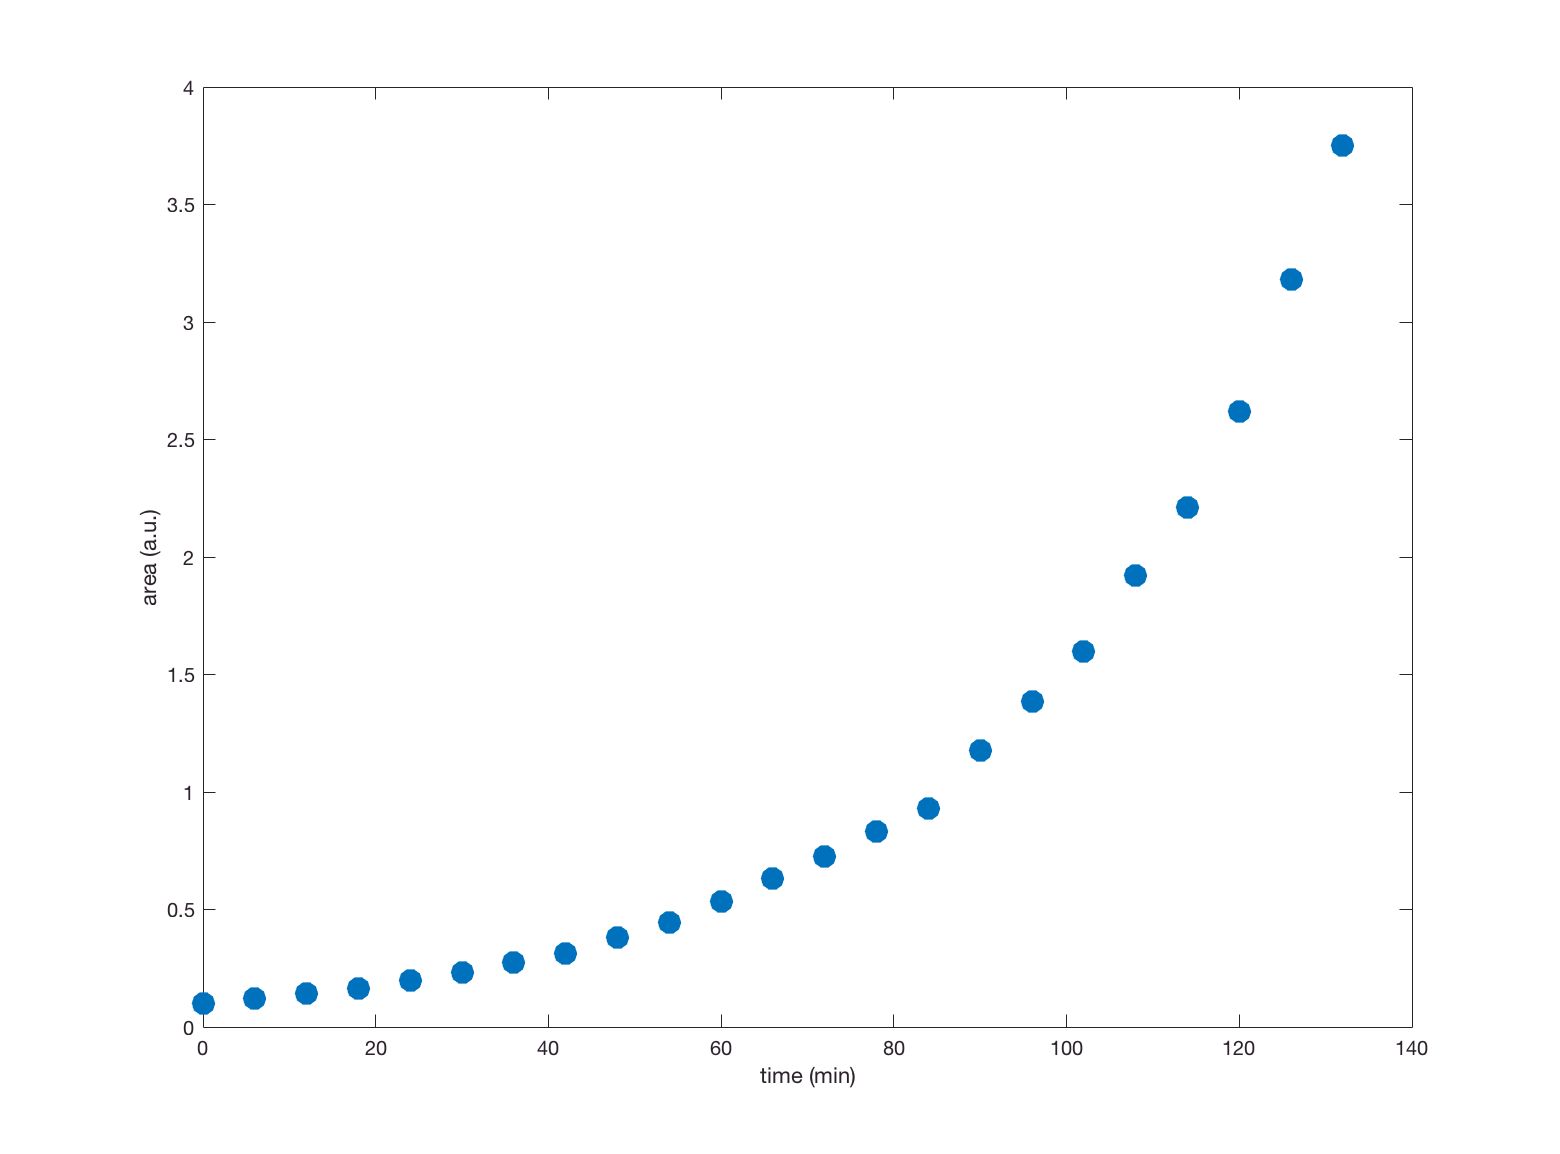

plot(t, areas / 1e5, '.', 'markersize', 40);
xlabel('time (min)');
ylabel('area (a.u.)');

For future reference, we will write our results out in a CSV file, which is generally a good idea to do.

outMat = [t' areas'];
csvwrite('ecoli_growth.csv', outMat);

## Performing a regression to estimate growth rate

We will now perform a regression on the data to estimate the growth rate.  There are many ways we can do this, but we can take advantage of the structure of our model and perform a linear regression.  To do this, we note that


$$\ln A(t) = \ln A_0 + kt.$$


So, if we plot the area on a semilog plot, the growth curve should be linear with slope $k$.

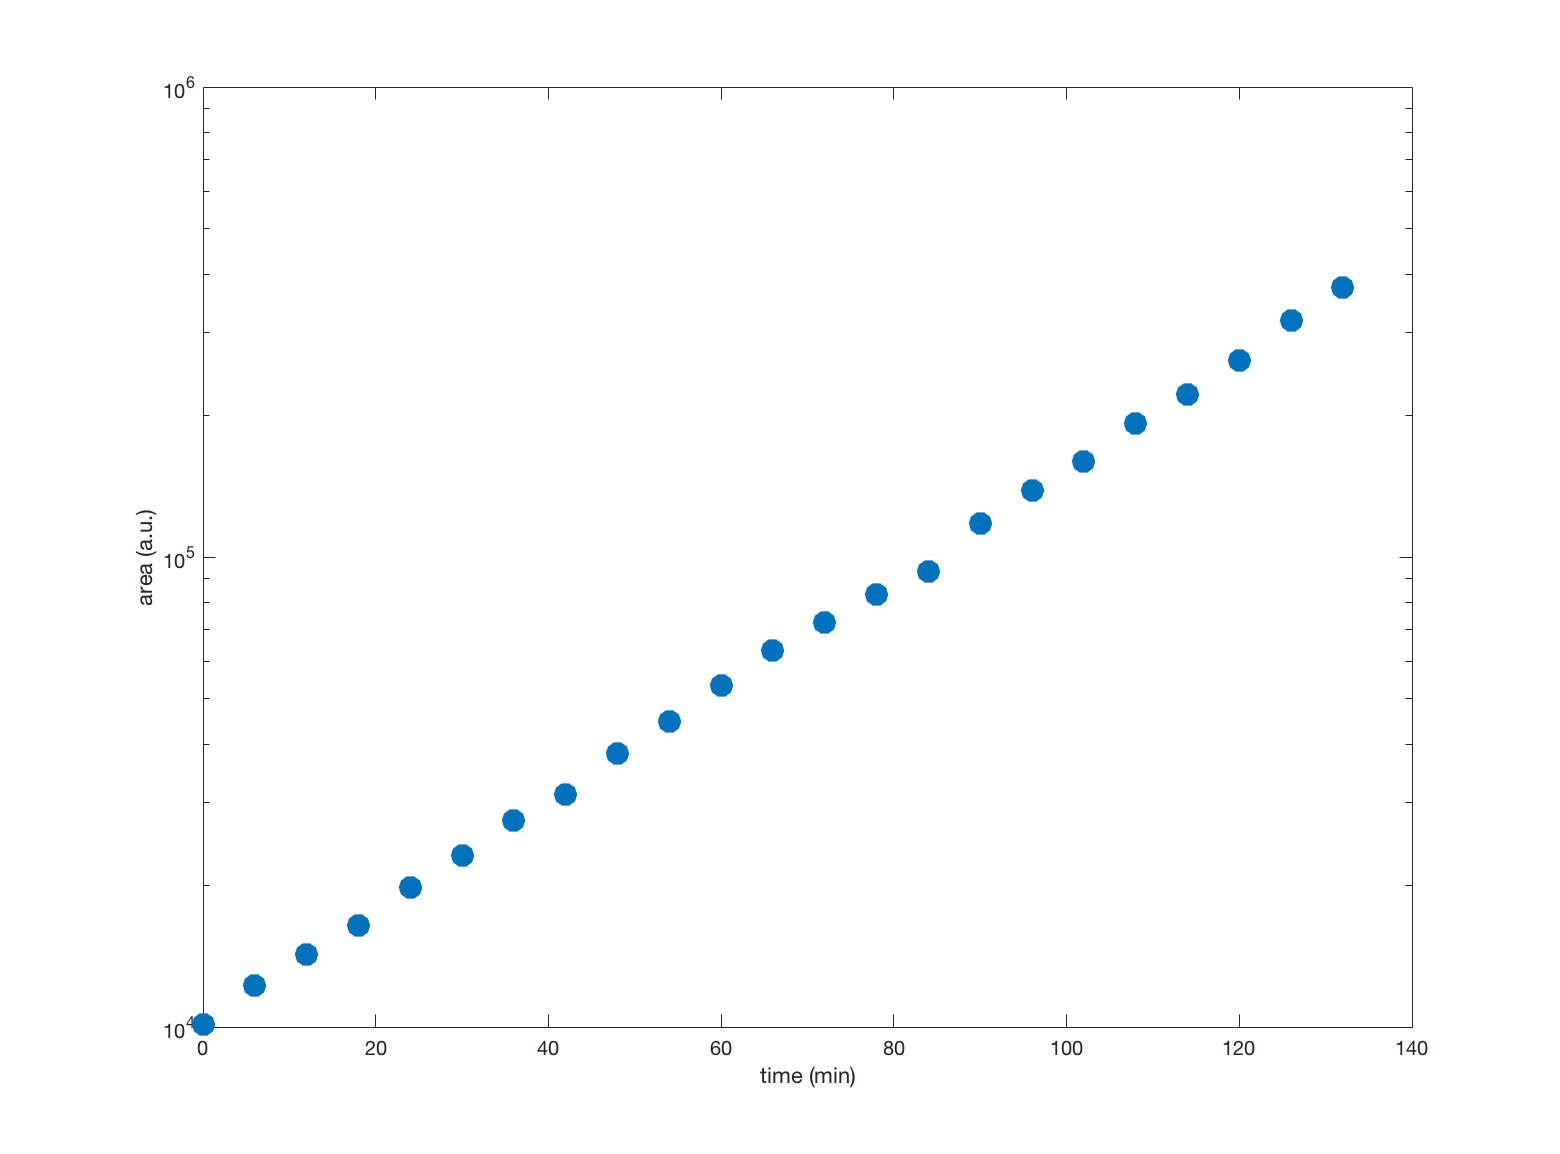

semilogy(t, areas, '.', 'markersize', 40);
xlabel('time (min)');
ylabel('area (a.u.)');

To perform the regression, we can use the `polyfit` functions, which fits curves with a polynomial of arbitrary degree.  Of course, we will fit our $t\text{-}\ln A$ data with a first order (linear) polynomial.

bestFitParams = polyfit(t, log(areas), 1)

bestFitParams =     0.0271    9.2366


The first entry in the output array is the slope and the second is the intercept.  So, we have the $k\approx 0.03 \text{ min}^{-1}.$  We can then compute the doubling time.

doublingTime = log(2) / bestFitParams(1)

doublingTime = 25.6034

These bacteria have a very fast doubling time of about 25 minutes.

Finally, let's plot our best-fit line through the data.

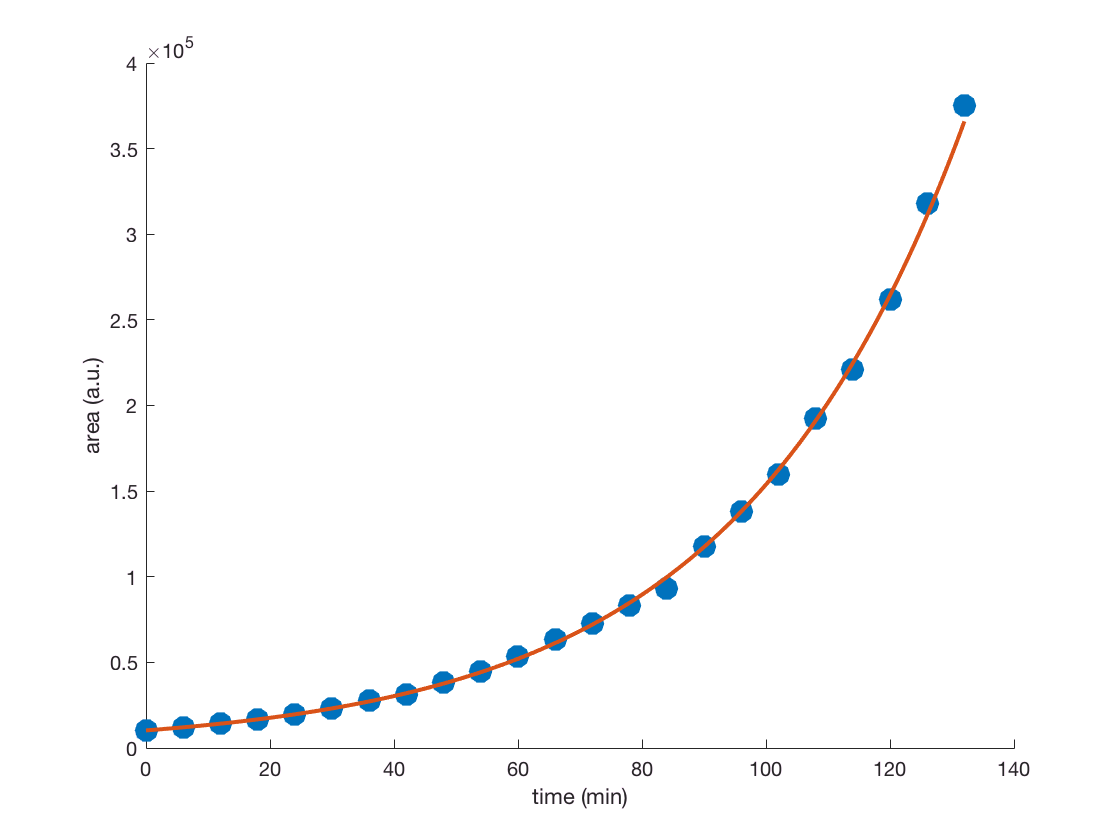

% Compute theoretical curve
tTheor = linspace(0, max(t), 200);
areasTheor = exp(bestFitParams(2)) * exp(bestFitParams(1) * tTheor);

figure();
hold on;
plot(t, areas,  '.', 'markersize', 40);
plot(tTheor, areasTheor, '-', 'linewidth', 2);
xlabel('time (min)');
ylabel('area (a.u.)');

Nice!

## Estimation of error in parameter value

We see qualitatively that we have a good fit to the data.  But how much wiggle room is there in the parameter value of 25 minutes that we estimated?  To compute this, we will use a **bootstrap** method.  We have measured time-area pairs, and out theoretical curve should be close to these values.  But there is some variability from measurement to measurement off of what we would expect from the theoretical curve.  This distance from the theoretical curve to the measured point is called a **residual**.  We can imagine that if we repeated the experiment, our data might vary from the curve in a similar, but quantitatively different ways.  In this other experiment, we might expect our curve fit routine to give us a bit of a different result.  We could then repeat the experiment, analysis, and curve fit over and over again, each time recording the values of the parameters we got from our curve fit.  The degree to which our growth rate varies from experiment to experiment gives us a confidence interval for its value.

Instead of doing that experiment, we will *simulate* the experiment.  Specifically, we will take our computed theoretical curve and generate new data by randomly choosing one of our measured residuals and making a data point that moves off of the theoretical curve by that amount.

This procedure of sampling different parameter values is implemented in Matlab's `bootstrp` function.  To use it, we first need to write a function to generate simulated data and our curve fits.  We of course need to compute the theoretical curve and the residuals to be able to draw from them.

% Generate theoretical values at experimental time points
areaTheor = exp(bestFitParams(2)) * exp(bestFitParams(1) * t);

% Compute residuals
resids = areas - areaTheor;

% Function to do curve fit with simulated data
ecoliFit = @(bootResid) polyfit(t, log(areaTheor + bootResid), 1);

Now, we will randomly select residuals to apply to each datum using the `randi` function, which randomly selects an integer that will serve as the index of the residual to add to the theoretical curve.

nSamples = 50000;
bootSamples = zeros(nSamples, 2);
for i = 1:nSamples
    bootResid = resids(randi(length(t), 1, length(t)));
    bootSamples(i,:) = ecoliFit(bootResid);
end %for

Let's look at a histogram of the bootstrap estimates for the rate.

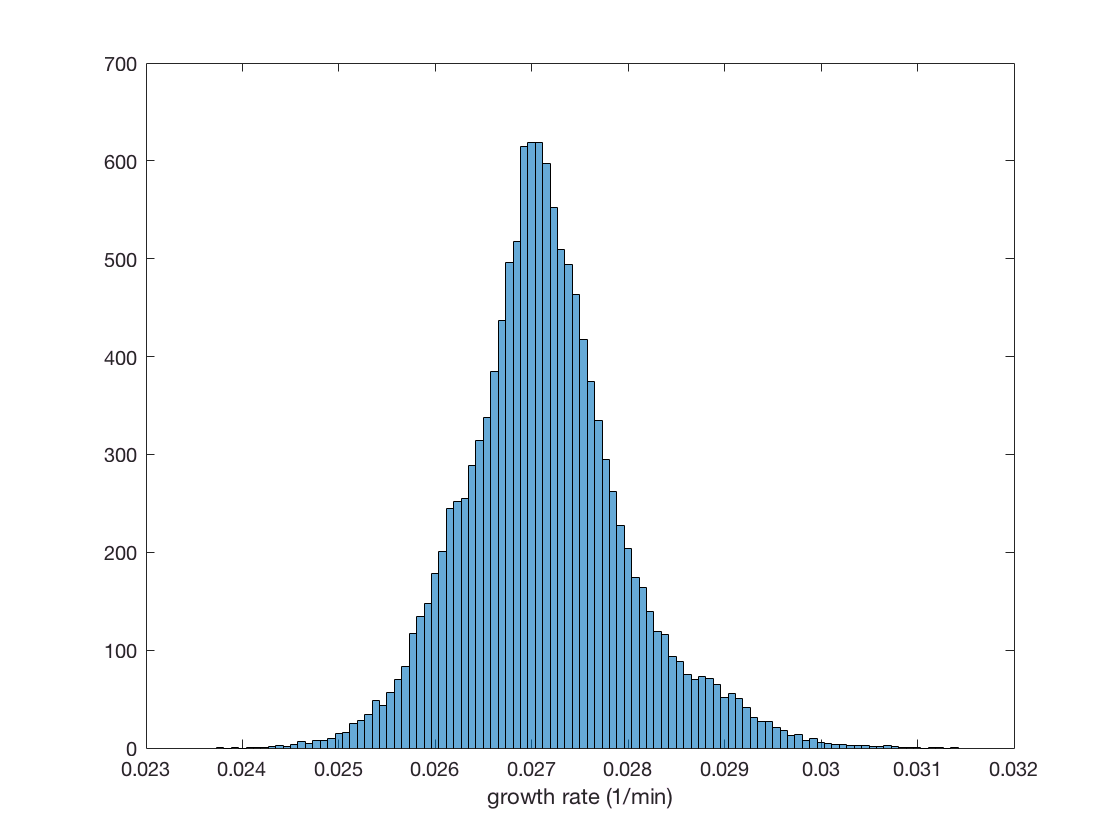

figure();
histogram(bootSamples(:,1), 100, 'normalization', 'pdf');
xlabel('growth rate (1/min)');

We see that the estimate we would get for the growth rate is non-Gaussian.  This isn't really a big deal, but worth knowing.  We will report out bootstrap confidence interval as the 95% confidence interval.  To do this, we use the `prctile` function on our bootstrap samples to get the upper and lower bounds on the confidence interval.

lowHigh = prctile(bootSamples, [2.5, 97.5]);
disp(lowHigh);

    0.0256    9.0536
    0.0291    9.3782



So, the growth rate confidence interval is [0.026, 0.029] inverse minutes, with a best-fit growth rate of 0.027 inverse minutes.  We would write the result of our curve fit as


$$k = 2.71^{+0.20}_{-0.15}\times 10^{-2}\text{ min}^{-1}.$$
